# Ejemplo Practico: Calcular punto medio de un segmento de recta.

El programa solicita al usuario por los puntos (x1,y1) y (x2,y2) de un segmento de recta, y calcula el punto medio del segmento de recta el cual esta ubicado en (xm,ym). Las coordenadas se calculan por:


$$x_m =\frac{1}{2}\left(x_1 +x_2 \right)$$



$$y_m =\frac{1}{2}\left(y_1 +y_2 \right)$$


Llamar las funciones

%Permiten conocer las coordenadas del punto inicial y final
[x1,y1] = ingresarCoordenadas('primer')

x1 = 3

y1 = 7

[x2,y2] = ingresarCoordenadas('segundo')

x2 = 9

y2 = 4


%Calcular las coordenadas del punto medio del segmento de recta.
mediox = encontrarPuntoMedio(x1,x2)

mediox = 6

medioy = encontrarPuntoMedio(y1,y2)

medioy = 5.5000

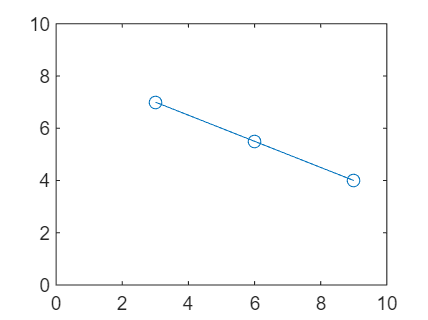


%graficar

vectorx = [x1,x2,mediox];
vectory = [y1,y2,medioy];

plot(vectorx,vectory,"LineStyle","-","Marker","o")
xlim([0 10])
ylim([0 10])

Crear las funciones

Funcion para leer y brindar las coordenadas que digite el usuario.

function [x,y] = ingresarCoordenadas(localizacion)
    solicitud = sprintf('Ingrese la coordenada x del %s punto ',localizacion);
    x = input(solicitud);
    solicitud = sprintf('Ingrese la coordenada y del %s punto ',localizacion);
    y = input(solicitud);
end

funcion para calcular el punto medio del segmento de recta

function puntoM = encontrarPuntoMedio(punto1,punto2)
    puntoM = 0.5*(punto1 + punto2);
end